%EE 354
%Quiz 2
%Lisa Jacklin
% 9/29/2022

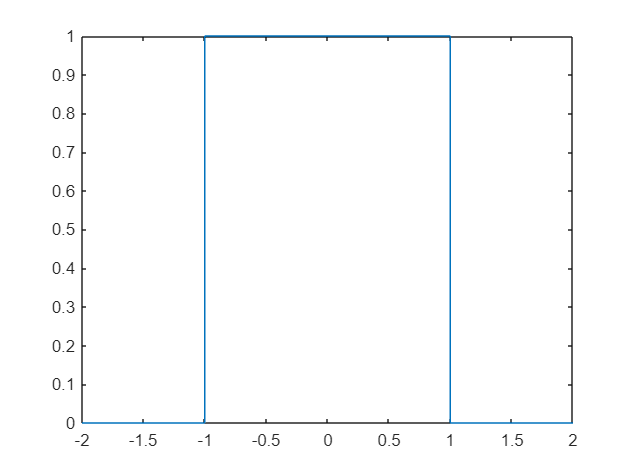

% Quiz 2 Problem 1 
%part f
clear
clf;

A = 1; %amplitude for V(f)
tc = 1; %time constant for V(f)
t1= -2; t2 = 2;

fs = 100; %sampling frequency

time = t1:tc:t2;
l = length(time);

%equation for v(t) with a for loop...
%only way i could make it work
t1=-2:0.01:-1; %time axis
t2=-1:0.01:1; %time axis 
t3=1:0.01:2; %time axis
t=[t1 t2 t3]; 

x1=zeros(size(t1)); %plotting 
x2=ones(size(t2));
x3=zeros(size(t3));
v=[x1 x2 x3];
plot(t,v);

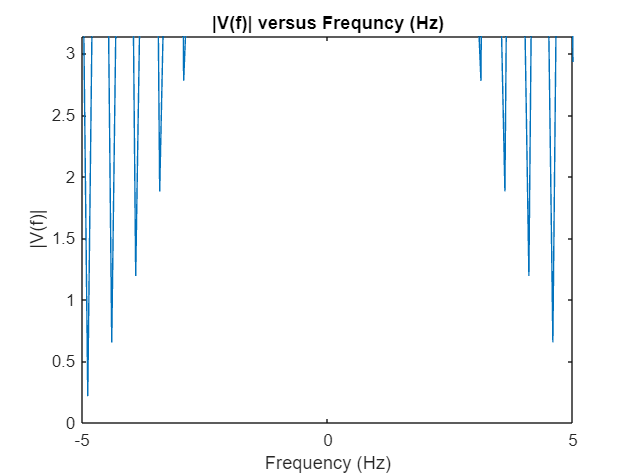

%we are not looking for v(t) so no need to plot
% Find the Fourier Transform.

M = 2^10;
Vf = tc*fftshift(fft(v,M));
% Generate frequency axis
df = fs/M;
freq = -(fs/2 - df):df:fs/2;


plot(freq,abs(Vf));
axis([-5 5 0 pi]) %axis is the same as in part g
xlabel('Frequency (Hz)')
ylabel('|V(f)|')
title('|V(f)| versus Frequncy (Hz)')

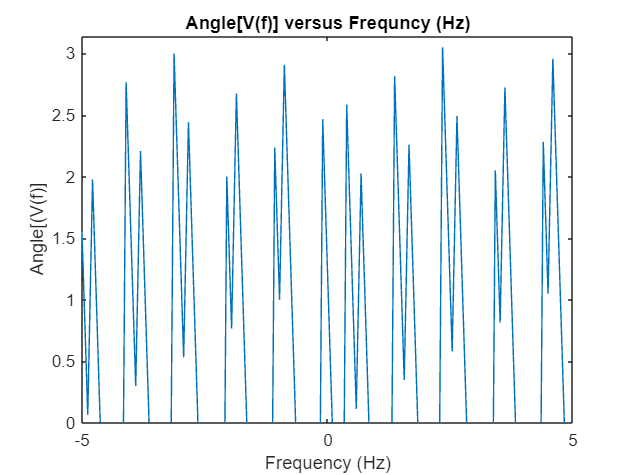

% Quiz 2 Problem 1 
%part g : plot the phase of the fourier transform

plot(freq,angle(Vf)) %this will describe the angle of Vf
axis([-5 5 0 pi]) %axis must be the same

xlabel('Frequency (Hz)')
 ylabel('Angle[(V(f)]')
 title('Angle[V(f)] versus Frequncy (Hz)')